close all
clear

%% set nice plotting
set(groot, 'defaultAxesTickLabelInterpreter','latex');
set(groot, 'defaultLegendInterpreter','latex');
set(groot, 'defaultGraphplotInterpreter','latex');
set(groot, 'defaultTextInterpreter','latex');
set(groot, 'defaultAxesYGrid','on')
set(groot, 'defaultAxesXGrid','on')
set(groot, 'defaultAxesBox','on')
set(groot, 'defaultAxesYMinorTick','on')
set(groot, 'defaultAxesXMinorTick','on')
set(groot, 'defaultAxesYMinorGrid','on','defaultAxesYMinorGridMode','manual')
set(groot, 'defaultAxesXMinorGrid','on','defaultAxesXMinorGridMode','manual')
set(groot, 'defaultAxesFontSize', 14)
set(groot, 'defaultColorbarFontSize',12)
set(groot, 'defaultLegendFontSize', 10)
set(groot, 'defaultTextFontSize', 14)



## Main

environment = struct with fields:
    length: 0.5000
    optics: [3×1 struct]


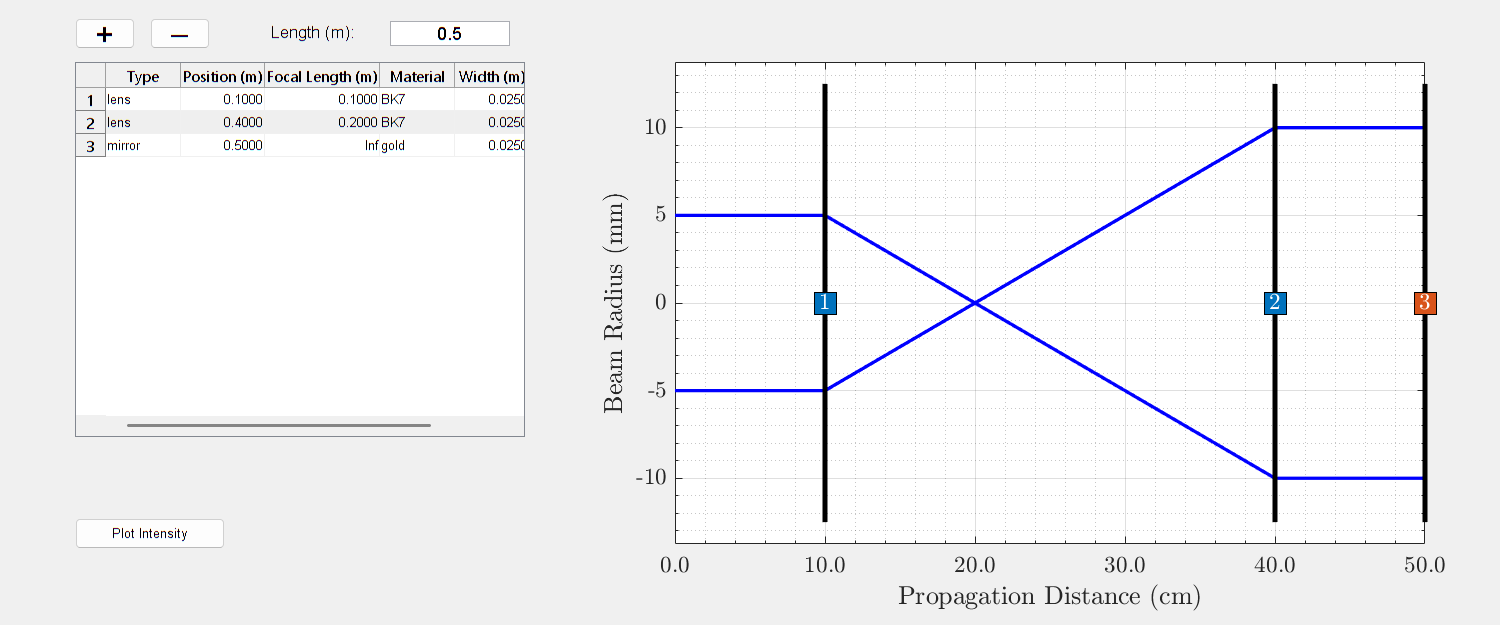

ray_trace_ui_with_table()

## Plot Ray Traces

function ray_trace_ui_with_table
    % Define initial laser and lens environment
    laser = struct();
    laser.energy = 5e-3;
    laser.width = 10e-3;
    laser.wavelength = 800e-9;
    laser.duration = 50e-15;

    environment.length = 0.5;
    environment.optics = [
        struct('class','lens', 'position', 0.1, 'focal_length', 0.1, 'width', 25e-3, 'material', 'BK7','coating',1,'row_index',1)
        struct('class','lens', 'position', 0.4, 'focal_length', 0.2, 'width', 25e-3, 'material', 'BK7','coating',1,'row_index',2)
        struct('class','mirror','position',0.5,'focal_length',inf,'width',25e-3,'material','gold','coating',0.97,'row_index',3)
    ]

    % Set up figure and UI layout
    fig = figure('Name', 'Ray Tracer', ...
        'Position', [100, 100, 1200, 500]);

    ax = axes('Parent', fig, 'Units', 'normalized', ...
        'Position', [0.45, 0.13, 0.5, 0.77]);
    hold(ax, 'on');

    % Create global state
    global STATE
    STATE.laser = laser;
    STATE.environment = environment;
    STATE.ax = ax;

    % Launch table
    launchLensTable(fig);


    % Initial plot
    updateMultiLensRayPlot();
end

function updateMultiLensRayPlot()
    global STATE
    cla(STATE.ax); hold(STATE.ax, 'on');

    env = STATE.environment;
    laser = STATE.laser;
    optics = env.optics;


    lambda = laser.wavelength;
    w0 = laser.width / 2;
    q = 1i * pi * w0^2 / lambda;

    for i = 1:length(optics)
        optics(i).row_index = i;
    end

    optics = sortrows(struct2table(optics), 'position');
    optics = table2struct(optics);

    z_all = []; w_all = [];
    z_start = 0;

    for i = 1:length(optics)+1
        if i <= length(optics)
            z_end = optics(i).position;
        else
            z_end = env.length;
        end

        z_seg = linspace(z_start, z_end, 200);
        q_seg = propagateGaussianABCD(q, z_seg - z_start);
        w_seg = getBeamRadius(q_seg, lambda);

        z_all = [z_all, z_seg];
        w_all = [w_all, w_seg];

        if i <= length(optics)
            q = q_seg(end);
            f = optics(i).focal_length;
            M = [1 0; -1/f 1];
            q = (M(1,1)*q + M(1,2)) / (M(2,1)*q + M(2,2));
            z_start = z_end;
        end
    end

    plot(STATE.ax, z_all,  w_all*1e3, 'b', 'LineWidth', 2);
    plot(STATE.ax, z_all, -w_all*1e3, 'b', 'LineWidth', 2);

    STATE.laser.z_all = z_all;
    STATE.laser.w_all = w_all;

    % Draw optics
    for i = 1:length(optics)
        x = optics(i).position;
        w = optics(i).width * 1e3 / 2;
        line(STATE.ax, [x x], [-w w], 'Color', 'k', 'LineWidth', 3);
        switch lower(optics(i).class)
            case 'lens'
                col = [0 0.4470 0.7410];   % blue
            case 'mirror'
                col = [0.8500 0.3250 0.0980];  % red
            case 'glass'
                col = [0.4660 0.6740 0.1880];  % green
            otherwise
                col = [0.5 0.5 0.5];       % gray
        end
        scatter(x, 0, 300, col, 's', 'filled', 'MarkerEdgeColor', 'k');
        text(x, 0, num2str(optics(i).row_index), ...
            'FontSize',14, ...
            'HorizontalAlignment', 'center', ...
            'VerticalAlignment', 'middle', ...
            'FontWeight', 'bold', ...
            'Color', 'w');  % white text for contrast
    end

    ylabel(STATE.ax, 'Beam Radius (mm)');
    xlim(STATE.ax, [0 env.length]);
    ylim(STATE.ax, [-1.1*max([optics.width w_all]), 1.1*max([optics.width w_all])].*0.5e3);
    grid(STATE.ax, 'on');

    xticks = get(STATE.ax, 'XTick');
    xticklabels = arrayfun(@(x) sprintf('%.1f', x*100), xticks, 'UniformOutput', false);
    set(STATE.ax, 'XTickLabel', xticklabels);
    xlabel(STATE.ax, 'Propagation Distance (cm)');
end

function launchLensTable(fig)
    global STATE

    optics = STATE.environment.optics;
    n = length(optics);

    data = cell(n, 6);
    for i = 1:n
        data{i, 1} = optics(i).class;
        data{i, 2} = optics(i).position;
        data{i, 3} = optics(i).focal_length;
        data{i, 4} = optics(i).material;
        data{i, 5} = optics(i).width;
        data{i, 6} = optics(i).coating;
    end

    column_names = {'Type', 'Position (m)', 'Focal Length (m)', 'Material', 'Width (m)','Coating (0-1)'};

    STATE.uitableHandle = uitable(fig, 'Data', data, ...
        'ColumnName', column_names, ...
        'ColumnEditable', [true true true true true true], ...
        'Units', 'normalized', ...
        'Position', [0.05, 0.3, 0.3, 0.6], ...
        'CellEditCallback', @onTableEdit);

    % Add '+' button (Add Lens)
    btnAddLens = uicontrol(fig, 'Style', 'pushbutton', 'String', '+', ...
        'Units', 'normalized', 'Position', [0.05, 0.92, 0.04, 0.05], ...
        'FontSize', 18, 'Callback', @addLensCallback);
    
    % Add '−' button (Remove Lens)
    btnRemoveLens = uicontrol(fig, 'Style', 'pushbutton', 'String', '−', ...
        'Units', 'normalized', 'Position', [0.10, 0.92, 0.04, 0.05], ...
        'FontSize', 18, 'Callback', @removeLensCallback);
    
    % Simulation Length label (compact)
    uicontrol(fig, 'Style', 'text', 'String', 'Length (m):', ...
        'Units', 'normalized', 'Position', [0.18, 0.915, 0.1, 0.05], ...
        'HorizontalAlignment', 'left', 'FontSize', 10);
    
    % Simulation Length edit box (compact)
    editLength = uicontrol(fig, 'Style', 'edit', ...
        'String', num2str(STATE.environment.length), ...
        'Units', 'normalized', 'Position', [0.26, 0.925, 0.08, 0.04], ...
        'FontSize', 11, 'Callback', @updateLengthCallback);

    % Calculate the intensity profile
    uicontrol('Style', 'pushbutton', 'String', 'Plot Intensity', ...
    'Units', 'normalized', 'Position', [0.05, 0.12, 0.1, 0.05], ... 
    'Callback', @plotIntensityCallback);

end

function onTableEdit(src, event)
    global STATE

    data = get(src, 'Data');
    n = size(data, 1);

    new_optics = repmat(struct('class','lens', 'position', 0, 'focal_length', 0, ...
        'width', 0, 'material', 'BK7','coating',1,'row_index',1), 1, n);

    for i = 1:n
        new_optics(i).class        = data{i, 1};
        new_optics(i).position     = data{i, 2};
        new_optics(i).focal_length = data{i, 3};
        new_optics(i).material     = data{i, 4};
        new_optics(i).width        = data{i, 5};
        new_optics(i).coating      = data{i, 6};
        new_optics(i).row_index    = i;
    end

    STATE.environment.optics = new_optics;
    updateMultiLensRayPlot();
end

function q_vals = propagateGaussianABCD(q_in, dz)
    % dz: vector of distances (can be multiple points)
    A = 1; B = dz;
    C = 0; D = 1;
    q_vals = (A .* q_in + B) ./ (C .* q_in + D);
end


function w = getBeamRadius(q, lambda)
    % Extract beam radius from q-parameter
    w = sqrt(-lambda ./ (pi * imag(1 ./ q)));
end


function addLensCallback(~, ~)
    global STATE
    % Add a new lens with default parameters at the end of the environment.optics array
    newOptic = struct('class','lens', 'position', 0.25, 'focal_length', 0.1, 'width', 25e-3, 'material', 'BK7','coating',1,'row_index',length(STATE.environment.optics)+1)
    STATE.environment.optics;
    STATE.environment.optics(end+1) = newOptic;
    
    % Refresh the table and plot
    updateLensTable();
    updateMultiLensRayPlot();
end

function updateLengthCallback(src, ~)
    global STATE
    newLength = str2double(get(src, 'String'));
    if isnan(newLength) || newLength <= 0
        % Reject invalid input, reset to previous valid value
        set(src, 'String', num2str(STATE.environment.length));
        errordlg('Please enter a positive numeric value for length', 'Invalid Input');
        return
    end
    STATE.environment.length = newLength;
    updateMultiLensRayPlot();
end

function removeLensCallback(~, ~)
    global STATE

    % Ask user for row number
    answer = inputdlg('Enter the row number of the optic to remove:', ...
                      'Remove Optic', [1 50]);

    if isempty(answer)
        return; % User cancelled
    end

    row = str2double(answer{1});

    % Validate input
    if isnan(row) || row < 1 || row > length(STATE.environment.optics)
        errordlg('Invalid row number.', 'Error');
        return;
    end

    % Remove optic
    STATE.environment.optics(row) = [];

    % Re-index
    for i = 1:length(STATE.environment.optics)
        STATE.environment.optics(i).row_index = i;
    end

    % Update UI
    updateLensTable();
    updateMultiLensRayPlot();
end


function updateLensTable()
    global STATE
    optics = STATE.environment.optics;
    n = length(optics);
    data = cell(n, 6);
    for i = 1:n
        data{i, 1} = optics(i).class;
        data{i, 2} = optics(i).position;
        data{i, 3} = optics(i).focal_length;
        data{i, 4} = optics(i).material;
        data{i, 5} = optics(i).width;
        data{i, 6} = optics(i).coating;
    end

    set(STATE.uitableHandle, 'Data', data);
end

function plotIntensityCallback(~, ~)
    global STATE

    % Create figure
    fig = figure('Name', 'Intensity Plot', ...
        'Position', [100, 100, 1200, 500]);

    % Input: Pulse Energy
    uicontrol('Style', 'text', 'String', 'Energy [J]:', ...
        'Position', [20, 450, 80, 20], 'HorizontalAlignment', 'right');
    energyBox = uicontrol('Style', 'edit', ...
        'String', num2str(STATE.laser.energy), ...
        'Position', [110, 450, 80, 25]);

    % Input: Pulse Duration
    uicontrol('Style', 'text', 'String', 'Duration [s]:', ...
        'Position', [20, 410, 80, 20], 'HorizontalAlignment', 'right');
    durationBox = uicontrol('Style', 'edit', ...
        'String', num2str(STATE.laser.duration), ...
        'Position', [110, 410, 80, 25]);

    % Button to update plot
    uicontrol('Style', 'pushbutton', 'String', 'Update Plot', ...
        'Position', [60, 370, 100, 30], ...
        'Callback', @(~,~) updateIntensityPlot(fig, energyBox, durationBox));
    
    % Initial plot call
    updateIntensityPlot(fig, energyBox, durationBox);
end

function updateIntensityPlot(fig, energyBox, durationBox)
    global STATE

    % Read new values
    E_pulse = str2double(energyBox.String);
    tau = str2double(durationBox.String);

    % Save into global state
    STATE.laser.energy = E_pulse;
    STATE.laser.duration = tau;

    % Clear old axes and tables
    delete(findall(fig, 'Type', 'axes'));
    delete(findall(fig, 'Type', 'uitable'));

    % Retrieve beam widths and positions
    z_vals = STATE.laser.z_all;
    w_vals = STATE.laser.w_all;

    % Intensity computation
    I_vals = 2 * E_pulse ./ (pi * w_vals.^2 * tau);

    % Axes
    ax = axes('Parent', fig, 'Units', 'normalized', ...
        'Position', [0.45, 0.13, 0.5, 0.77]);
    semilogy(ax, z_vals, I_vals);
    xlabel('Propagation Distance z [m]');
    ylabel('Intensity [Wm$^{-2}$]', 'Interpreter', 'latex');
    title('Laser Intensity Along Optical Path');
    grid on;
    hold(ax, 'on');

    % Optic scatter and fluence table
    fluenceData = {};
    for i = 1:length(STATE.environment.optics)
        optics = STATE.environment.optics(i);
        z_pos = optics.position;
        [~, idx] = min(abs(z_vals - z_pos));
        I_optic = I_vals(idx);
        F_optic = E_pulse / w_vals(idx);

        fluenceData{i, 1} = optics.row_index;
        fluenceData{i, 2} = optics.class;
        fluenceData{i, 3} = z_pos;
        fluenceData{i, 4} = I_optic;
        fluenceData{i, 5} = F_optic;

        % Optic type color
        switch lower(optics.class)
            case 'lens',   col = [0 0.4470 0.7410]; % blue
            case 'mirror', col = [0.8500 0.3250 0.0980]; % red
            case 'glass',  col = [0.4660 0.6740 0.1880]; % green
            otherwise,     col = [0.5 0.5 0.5]; % gray
        end

        scatter(ax, z_pos, I_optic, 300, col, 's', 'filled', 'MarkerEdgeColor', 'k');
        text(z_pos, I_optic, num2str(optics.row_index), ...
            'FontSize',14, 'HorizontalAlignment','center', ...
            'VerticalAlignment','middle', 'FontWeight','bold', 'Color','w');
    end

    % Fluence table
    uitable('Parent', fig, 'Data', fluenceData, ...
        'ColumnName', {'#', 'Type', 'z [m]', 'Intensity [W/m^2]', 'Fluence [J/m^2]'}, ...
        'Units', 'normalized', ...
        'Position', [0.05, 0.1, 0.3, 0.6]);
end